This assignment requires the use of KLT to compress images. The image selected is the most popular Lenna image in the field of image processing.

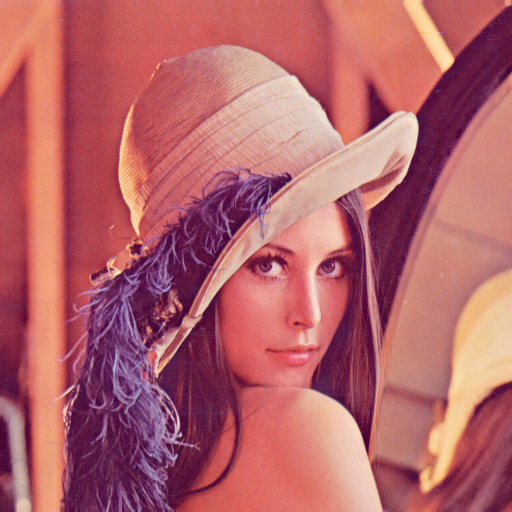

Original pic is 512*512*3 pixels in png format, pixel depth is 8bits.

tic

(1) read the pic and convert to grayscale

rgbimg = imread("Lenna.png");
grayimg = rgb2gray(rgbimg);
d_grayimg = im2double(grayimg);%for pca use
%{
subplot(1, 2, 1);
imshow(rgbimg);
title('Original Image');

subplot(1, 2, 2);
imshow(grayimg);
title('Grayscale Image');
%}

(2) for the 512*512 gray mat, perform partition

[rawrow_elements,rawcol_elements] = size(grayimg);
raw_elements = numel(grayimg);
subrow_elements = 16;
subcol_elements = 16;
sub_elements = subrow_elements*subcol_elements;
total_subblocks = raw_elements/sub_elements;

reshaped_img = zeros(sub_elements,total_subblocks);
new_column_counter = 1;%easier way against submatrix_rowindex and submatrix_colindex
for submatrix_rowindex = 1 : rawrow_elements/subrow_elements
    for submatrix_colindex = 1: rawcol_elements/subcol_elements
        %for each submat fill corresponding element
        cur_submat = grayimg(subrow_elements*(submatrix_rowindex-1)+1:subrow_elements*submatrix_rowindex, subcol_elements*(submatrix_colindex-1)+1:subcol_elements*submatrix_colindex);
        %rearrange to column vector
        cur_vector = reshape(cur_submat',[],1);
        
        %fill in mat C
        reshaped_img(:,new_column_counter) = cur_vector;
        new_column_counter = new_column_counter+1;

    end
end

(3) calc mean, perform normalization, calc covaiance


%calc the mean vec
mean_vec = mean(reshaped_img,2)

mean_vec =   123.6094
  123.8398
  124.2412
  124.2148
  124.1699
  124.0459
  123.9248
  124.4756
  124.7305
  124.6641



%now calc the covariance mat
reshaped_img_zeromean = reshaped_img - mean_vec

reshaped_img_zeromean =    38.3906   33.3906   30.3906   48.3906  -26.6094  -13.6094  -14.6094  -11.6094    8.3906   10.3906    4.3906   12.3906   11.3906   16.3906    7.3906   12.3906   14.3906    5.3906    2.3906   -2.6094  -19.6094   35.3906   27.3906   29.3906   29.3906   31.3906   96.3906   -7.6094   -0.6094   -1.6094    4.3906   -9.6094   32.3906   28.3906   37.3906   44.3906  -24.6094  -17.6094  -22.6094   -8.6094    6.3906   10.3906    8.3906    7.3906    5.3906    9.3906    2.3906   10.3906    7.3906    7.3906
   38.1602   32.1602   34.1602   48.1602  -26.8398  -15.8398  -13.8398   -1.8398    5.1602    2.1602   10.1602    9.1602   12.1602    8.1602    4.1602   10.1602   18.1602    3.1602    8.1602    0.1602  -11.8398   35.1602   33.1602   27.1602   33.1602   31.1602   92.1602   -6.8398   -1.8398    0.1602   -1.8398   -2.8398   32.1602   32.1602   39.1602   43.1602  -30.8398  -11.8398  -19.8398   -2.8398    4.1602    7.1602   10.1602   12.1602    7.1602   11.1602    4.1602    8


res = zeros(sub_elements,sub_elements);
for ind = 1:total_subblocks
    res = res + reshaped_img_zeromean(:,ind)*reshaped_img_zeromean(:,ind)';
end

cov = res./(size(reshaped_img_zeromean,2)-1)%divide by N-1 since no bias estimation

cov = 1.0e+03 *

    2.2081    2.1742    2.0856    1.9925    1.9110    1.8212    1.7299    1.6193    1.5396    1.4745    1.4321    1.3652    1.2804    1.1921    1.1288    1.0687    2.1858    2.1469    2.0532    1.9698    1.8944    1.7992    1.7015    1.6026    1.5246    1.4601    1.4138    1.3296    1.2567    1.1824    1.1166    1.0609    2.1564    2.1055    2.0209    1.9171    1.8418    1.7715    1.6821    1.5942    1.5157    1.4541    1.3875    1.3294    1.2518    1.1773    1.0976    1.0446    2.1084    2.0632
    2.1742    2.2910    2.2404    2.1338    2.0385    1.9356    1.8431    1.7292    1.6404    1.5635    1.5142    1.4566    1.3776    1.2845    1.2160    1.1530    2.1851    2.2578    2.2012    2.1085    2.0184    1.9075    1.8154    1.7164    1.6291    1.5530    1.4968    1.4192    1.3534    1.2773    1.2040    1.1410    2.1790    2.1993    2.1514    2.0517    1.9619    1.8793    1.7913    1.7013    1.6167    1.5466    1.4809    1.4188    1.3477    1.2768    1.1833    1.1186  

(4) calc eig

eigenvals = eig(cov)

eigenvals = 1.0e+05 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


[eigenvectors, D] = eig(cov);
eigenvectors;

(5) reconstruct img and calc the tse using different choice of retained principal components number

%%We want to sort the eigenvalues/vectors in descending order
%[sortedD, indexD] = sort(diag(D),'descend');
%sorted_eigenvectors = eigenvectors(:, indexD);
%%But we could find that eig() gives the vectors in ascending order, so
%%just flip it.

de_eigenvectors = fliplr(eigenvectors)

de_eigenvectors =     0.0520    0.0855    0.0285    0.1482    0.0178   -0.1340    0.0179    0.0465   -0.1028    0.0771    0.0261   -0.1388   -0.0420   -0.0048    0.1001    0.0143   -0.0331   -0.0019   -0.0295    0.2329    0.0310   -0.0963    0.0957    0.0584   -0.0344   -0.0966   -0.0071   -0.1356    0.1004    0.0194    0.1099    0.0214    0.1304   -0.1585   -0.0459   -0.0881    0.0646    0.0859   -0.0413    0.0169   -0.0262   -0.0093    0.0438   -0.0902    0.0754   -0.0678   -0.1614    0.0042   -0.0402   -0.0712
    0.0550    0.0854    0.0380    0.1489    0.0276   -0.1272   -0.0130    0.0480   -0.1059    0.0427    0.0810   -0.1120   -0.0321    0.0062    0.0870    0.0741   -0.0047   -0.0481    0.0020    0.1493    0.0668   -0.1049   -0.0110   -0.0124    0.0204   -0.0696   -0.0638   -0.0044    0.0154   -0.0521    0.0907    0.0320    0.0890   -0.0535    0.0244    0.1590    0.0039    0.1173   -0.0270    0.0047   -0.0053   -0.0188   -0.0391   -0.1003    0.0418   -0.0476   -0.0855    0.0236 

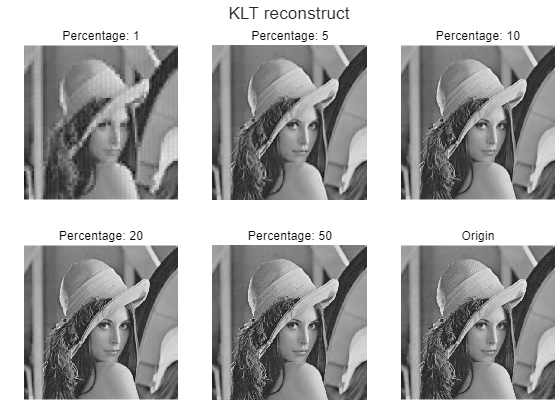


%when calc the each 1% steps of reconstruct data, we want to use the
%previously calculated result, as previous_result

reconstruct_img_not_dereshaped = zeros(sub_elements,total_subblocks);

scatter_x = [];
scatter_y = [];
tile = tiledlayout(2,3,"TileSpacing","compact","Padding","tight");
img_array = cell(1,6);
for ii = 1:5
    img_array{ii} = zeros(512,512,'uint8');% store the reconstruct img of 1% 5% 10% 20% 50% principal components and origin img
end
img_array{6} = grayimg;
draw_percentage = [1 5 10 20 50];

%calc tse at each percentage of retained/total
startp = 0.25;
stepp = 0.25;
endp = 100;
for percentage = startp:stepp:endp
    retained_num = round(sub_elements/100*percentage);
    last_retained_num = round(sub_elements/100*(percentage-stepp));

    for current_cnt = (last_retained_num+1):retained_num
        reconstruct_img_not_dereshaped = reconstruct_img_not_dereshaped + de_eigenvectors(:,current_cnt)*(de_eigenvectors(:,current_cnt)')*reshaped_img_zeromean;
    end
    
    reconstruction_tse = norm(reconstruct_img_not_dereshaped - reshaped_img_zeromean)^2;

    scatter_x = [scatter_x, percentage];
    scatter_y = [scatter_y, reconstruction_tse];

    if ismember(percentage,draw_percentage)
        %dereshape the pic
        current_havemean = reconstruct_img_not_dereshaped + mean_vec;
        for subblock_cnt = 1: total_subblocks
            current_dereshaped_subblock = (reshape(current_havemean(:,subblock_cnt), subrow_elements, subcol_elements))';
            sub_in_row = (subblock_cnt-1)/(rawrow_elements/subrow_elements);%start from 0 to 3, block 4 is in row0 block 16 is in row 3
            sub_in_row = floor(sub_in_row);
            sub_in_col = mod(subblock_cnt-1,rawrow_elements/subrow_elements);%start from 0 to 3
            img_array{find(draw_percentage == percentage)}(sub_in_row*subrow_elements+1:(sub_in_row+1)*subrow_elements,sub_in_col*subrow_elements+1:(sub_in_col+1)*subrow_elements) = current_dereshaped_subblock;
        end
        nexttile
        imshow(img_array{find(draw_percentage == percentage)})
        %curstring = num2str(percentage);
        curstring = sprintf('Percentage: %d' , percentage);
        title(curstring);
    

    end
end

nexttile
imshow(img_array{6})
title('Origin')
sgtitle('KLT reconstruct')

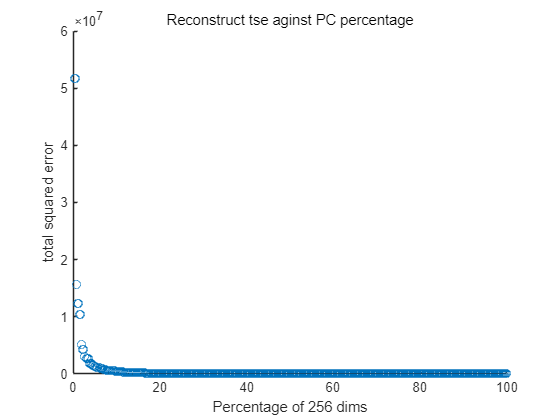


figure;
scatter(scatter_x,scatter_y);
title('Reconstruct tse aginst PC percentage');
xlabelstr = sprintf('Percentage of %d dims',sub_elements);
ylabelstr = sprintf('total squared error');
xlabel(xlabelstr);
ylabel(ylabelstr);

%pause

(6) lastly, use the intrinsic pca function to make a compare.

% 主成分分析
[coeffs, pcaData, ~, ~, explained] = pca(d_grayimg);


% 根据解释方差计算成分数量
enoughExplained = cumsum(explained)/sum(explained) >= 60/100;
numberOfComponentsToKeep = find(enoughExplained, 1);
disp("解释至少 60% 的方差所需的成分数目为 "+ num2str(numberOfComponentsToKeep))

解释至少 60% 的方差所需的成分数目为 5


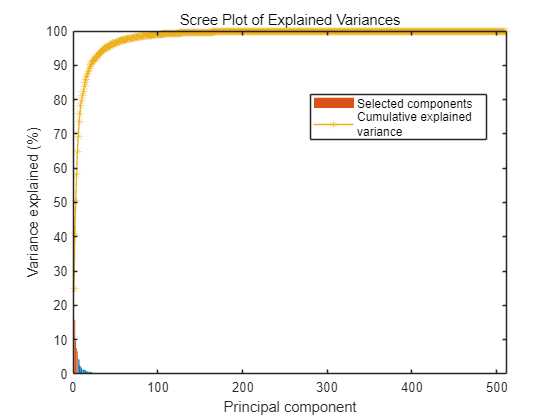


% 显示结果
figure
colorMap = colormap("lines");
barPlot = bar(explained);
hold on;
plot(cumsum(explained),"*-","Color",colorMap(3,:));
hold off;
barPlot(1).FaceColor = "flat";
barPlot(1).CData(1:numberOfComponentsToKeep,:) = repmat( ...
    colorMap(2,:),[numberOfComponentsToKeep 1]);
label = ["Selected components"; sprintf("Cumulative explained\nvariance")];
legend(label,"Location","best");
title("Scree Plot of Explained Variances")
xlabel("Principal component")
ylabel("Variance explained (%)")

clear barPlot colorMap label explained
clear coeffs enoughExplained explained
pcaData = pcaData(:,1:numberOfComponentsToKeep);
clear numberOfComponentsToKeep
toc

历时 13.161223 秒。
